# One Patient

Analyze data about one patient:

- Extract EEG data

- Apply Laplacian filter and compute PSD

- Choose discriminant features using Fisher score

- Train and save a classifier

- Evaluate performance with and without evidence accumulation

patients = find_patients('data');
patient = patients{8};

disp(strcat('Beginning data Analysis for patient: ', patient.name));

Beginning data Analysis for patient:aj9



info.fixation_code = 786;
info.cue_BH = 773;
info.cue_BF = 771;
info.cue_rest = 783;
info.feedback_code = 781;
info.offline_mode = 0;
info.online_mode = 1;

info.selected_frequencies = (4:2:48)';
info.channel_labels  = {'Fz', 'FC3', 'FC1', 'FCz', 'FC2', 'FC4', 'C3', 'C1', 'Cz', 'C2', 'C4', 'CP3', 'CP1', 'CPz', 'CP2', 'CP4'};
info.num_features = 3;

% Weights for channels and frequencies.
feature_weights = load('features_filter.mat').features_filter';

PSD_data = {};
for f = 1:length(patient.offline_files)
    % Raw EEG
    [s, h] = sload(patient.offline_files{f});
    
    % Apply Lap and compute PSD
    PSD_data{end+1} = psd_extraction(s, h);
    PSD_data{end}.modality = info.offline_mode;
end

[proc] |- Applying Laplacian
[proc] |- Computing spectrogram
[proc] |- Extracting and converting the events
[proc] |- Applying Laplacian
[proc] |- Computing spectrogram
[proc] |- Extracting and converting the events
[proc] |- Applying Laplacian
[proc] |- Computing spectrogram
[proc] |- Extracting and converting the events


for f = 1:length(patient.online_files)
    % Raw EEG
    [s, h] = sload(patient.online_files{f});
    
    % Apply Lap and compute PSD
    PSD_data{end+1} = psd_extraction(s, h);
    PSD_data{end}.modality = info.online_mode;
end

[proc] |- Applying Laplacian
[proc] |- Computing spectrogram
[proc] |- Extracting and converting the events
[proc] |- Applying Laplacian
[proc] |- Computing spectrogram
[proc] |- Extracting and converting the events
[proc] |- Applying Laplacian
[proc] |- Computing spectrogram
[proc] |- Extracting and converting the events
[proc] |- Applying Laplacian
[proc] |- Computing spectrogram
[proc] |- Extracting and converting the events
[proc] |- Applying Laplacian
[proc] |- Computing spectrogram
[proc] |- Extracting and converting the events
[proc] |- Applying Laplacian
[proc] |- Computing spectrogram
[proc] |- Extracting and converting the events



% We assume all frequencies to be the same for all data.
original_frequencies = PSD_data{1}.frequencies;

Concatenate data and create cue and trial vectors

[psd, events, run_k, mode_k] = concatenatePSD(PSD_data);
[cue_k, trial_k] = labelData(events, size(psd, 1));

% Extract the desired frequencies.
[psd, psd_frequencies] = extractFrequencies(psd, original_frequencies, info.selected_frequencies);

% Apply log to psd
psd = log(psd);

Cache a few useful indices

offline_data = mode_k == info.offline_mode;
online_data = mode_k == info.online_mode;
bh_data = cue_k == info.cue_BH;
bf_data = cue_k == info.cue_BF;
bh_bf_data = bh_data | bf_data;

Extract features to train a classifier

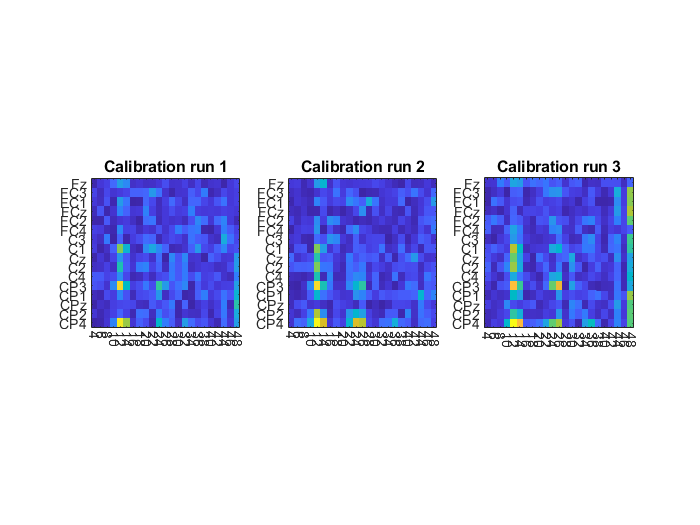

classes = [info.cue_BF, info.cue_BH];
[selected_features, fisher_score_run] = psd2features( ...
    psd(offline_data, :, :), run_k(offline_data), cue_k(offline_data), ...
    classes, info.num_features, feature_weights ...
    );

plot_fisher_score(info, psd_frequencies, fisher_score_run);

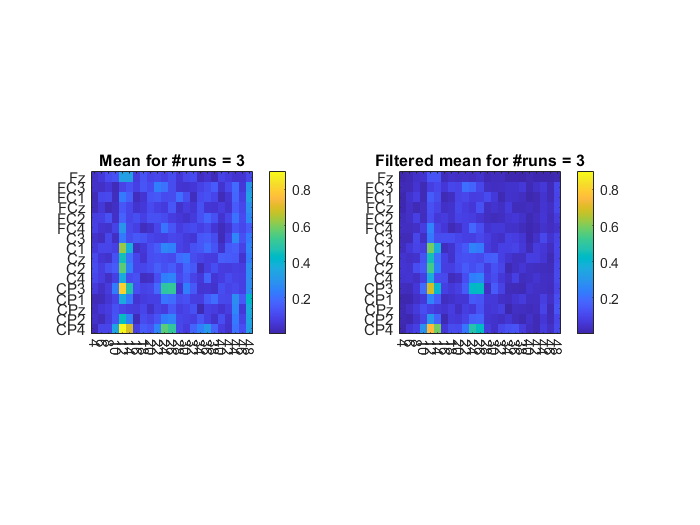

plot_average_fisher(info, psd_frequencies, fisher_score_run, feature_weights);

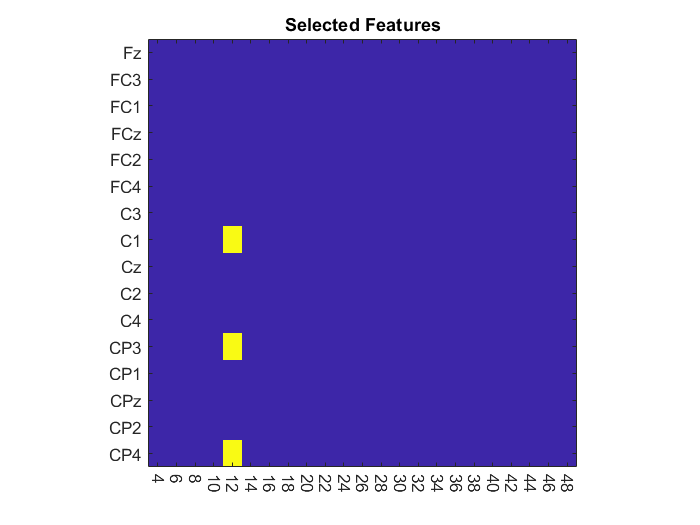

plot_selected_features(info, psd_frequencies, fisher_score_run, selected_features);

# Single sample classification

X = extractFeatures(psd, selected_features);
training_set = X(offline_data & bh_bf_data, :);
training_labels = cue_k(offline_data & bh_bf_data);

test_set = X(online_data & bh_bf_data, :);
test_labels = cue_k(online_data & bh_bf_data);

## Choose a model using cross validation

model = train_binary_model(training_set, training_labels);

Model 1 obtained an average test accuracy of: 77.856780.
Model 2 obtained an average test accuracy of: 78.648042.
Model 3 obtained an average test accuracy of: 79.328136.


% Results on training set
predicted_labels = predict(model, training_set);
accuracy_tot = 100*sum(training_labels == predicted_labels)/length(training_labels)

accuracy_tot = 79.4669

accuracy_bh = 100*sum(predict(model, X(offline_data & bh_data, :)) == info.cue_BH)/sum(offline_data & bh_data)

accuracy_bh = 84.2821

accuracy_bf = 100*sum(predict(model, X(offline_data & bf_data, :)) == info.cue_BF)/sum(offline_data & bf_data)

accuracy_bf = 74.6530

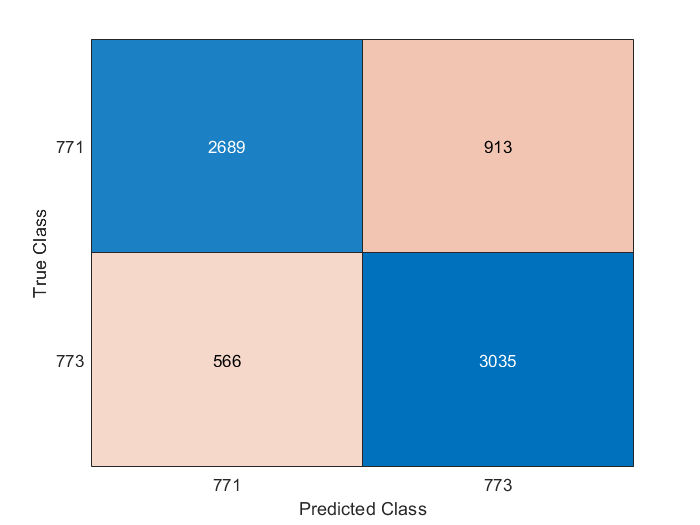

confusionchart(training_labels, predicted_labels);


% Results on test set
predicted_labels_test = predict(model, test_set);
accuracy_test = 100*sum(test_labels == predicted_labels_test)/length(test_labels)

accuracy_test = 71.2381

accuracy_bh_test = 100*sum(predict(model, X(online_data & bh_data, :)) == info.cue_BH)/sum(online_data & bh_data)

accuracy_bh_test = 83.4592

accuracy_bf_test = 100*sum(predict(model, X(online_data & bf_data, :)) == info.cue_BF)/sum(online_data & bf_data)

accuracy_bf_test = 53.7547

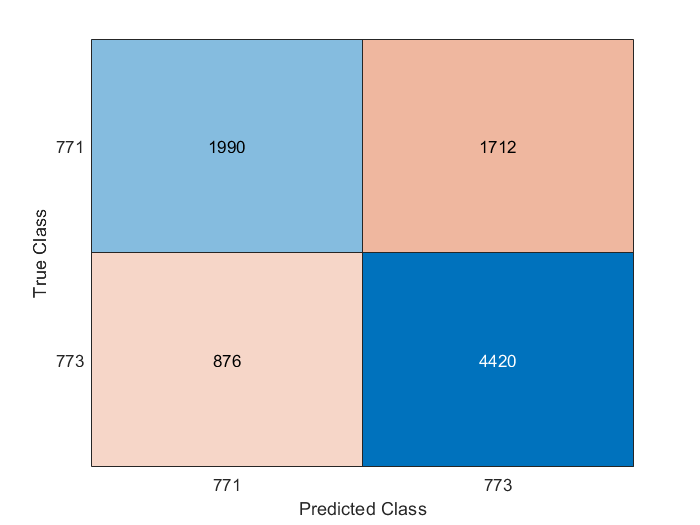

confusionchart(test_labels, predicted_labels_test);

# Evidence Accumulation

classify and accumulate evidence over the feedback period of online runs

the evidence accumulation is based on the posterior probability of class 771 both feet

% We use evidence accumulation on online data.
accumulation_data = X(online_data, :);
[~, post_probabilities] = predict(model, accumulation_data);

num_samples = length(accumulation_data);
num_classes = length(classes);

% reset accumulation to the base probability of this class = 1/num_classes
reset_accumulation = 1./num_classes;
% vector of start of feedback for each trial
feedback_starts = events.POS(events.TYP == info.feedback_code & events.MOD == info.online_mode);
%shift to manage only data in online part
feedback_starts = feedback_starts - sum(offline_data);

## Exponential smoothing

% coefficient that determines how the system respond to the new sample (high-> conservative, low->responsive)
alpha_ex = 0.9;

% compute accumulator
accumulator_ex = exponential_smoothing(post_probabilities, num_classes, feedback_starts, alpha_ex);

## Dynamic smoothing

% coefficient that determines how the system respond to the new sample (high-> conservative, low->responsive)
alpha_dyn = 0.5;
beta = 0.11;
conservative_amp = 0.1;
w = 0.3;
free_force_function = @(x) f_free(x,conservative_amp,w);
bmi_force_function = @(x) f_bmi_sin(x);

% compute accumulator
accumulator_dyn = dynamic_smoothing(post_probabilities, num_classes, feedback_starts, alpha_dyn, beta, free_force_function, bmi_force_function);

## Moving average

alpha_mov = 0.4;
% compute accumulator
accumulator_mov = mov_avg_smoothing(post_probabilities, num_classes, feedback_starts, alpha_mov);

# Evidence accumulation performance

% Select only online trials.
trial_online = trial_k(online_data);
% index for the feedback part of the data used in accumulation
feedback_index = getLabelsForEventType(events, info.feedback_code, size(psd, 1));
% scale down feedback index to online data
feedback_online = feedback_index(online_data);
% vector of true class for the trial
true_class = events.TYP((events.TYP == info.cue_BF | events.TYP == info.cue_BH | events.TYP == info.cue_rest) & events.MOD == info.online_mode);

up_threshold_ex = 0.7;
down_threshold_ex = 0.3;
up_threshold_dyn = 0.7;
down_threshold_dyn = 0.3;
up_threshold_mov = 0.7;
down_threshold_mov = 0.3;

[perf_active_ex, perf_resting_ex, perf_active_rej_ex] = evaluate_accumulation( ...
    up_threshold_ex, down_threshold_ex, true_class, accumulator_ex, feedback_online, trial_online ...
)

perf_active_ex = 72.5000

perf_resting_ex = NaN

perf_active_rej_ex = 84.4660

[perf_active_dyn, perf_resting_dyn, perf_active_rej_dyn] = evaluate_accumulation( ...
    up_threshold_dyn, down_threshold_dyn, true_class, accumulator_dyn, feedback_online, trial_online ...
)

perf_active_dyn = 67.5000

perf_resting_dyn = NaN

perf_active_rej_dyn = 90

[perf_active_mov, perf_resting_mov, perf_active_rej_mov] = evaluate_accumulation( ...
    up_threshold_mov, down_threshold_mov, true_class, accumulator_mov, feedback_online, trial_online ...
)

perf_active_mov = 57.5000

perf_resting_mov = NaN

perf_active_rej_mov = 61.6071

function fig = plot_fisher_score(info, psd_frequencies, fisher_score)

M = max(fisher_score, [], 'all');
m = min(fisher_score, [], 'all');
runs = size(fisher_score, 3);
freq = size(fisher_score, 1);
chan = size(fisher_score, 2);
handles = nan(runs, 1);
fig = figure;

for r = 1:runs
    subplot(1, runs, r);
    imagesc(fisher_score(:, :, r)');
    axis square;
    set(gca, 'XTick', 1:freq);
    set(gca, 'XTickLabel', psd_frequencies);
    set(gca, 'YTick', 1:chan);
    set(gca, 'YTickLabel', info.channel_labels);
    xtickangle(-90);
    title(['Calibration run ' num2str(r)]);
    caxis([m, M]);
    handles(r) = gca;
end

end

function fig = plot_average_fisher(info, psd_frequencies, fisher_score, feature_weights)

mean_fisher = mean(fisher_score, 3);
filt_fisher = mean_fisher .* feature_weights;

M = max(fisher_score, [], 'all');
m = min(fisher_score, [], 'all');
runs = size(fisher_score, 3);
freq = size(fisher_score, 1);
chan = size(fisher_score, 2);
fig = figure;

subplot(1,2,1);
imagesc(mean_fisher');
axis square;
set(gca, 'XTick', 1:freq);
set(gca, 'XTickLabel', psd_frequencies);
set(gca, 'YTick', 1:chan);
set(gca, 'YTickLabel', info.channel_labels);
xtickangle(-90);
colorbar;
caxis([m, M]);
title(['Mean for #runs = ' num2str(runs)]);

subplot(1,2,2);
imagesc(filt_fisher');
axis square;
set(gca, 'XTick', 1:freq);
set(gca, 'XTickLabel', psd_frequencies);
set(gca, 'YTick', 1:chan);
set(gca, 'YTickLabel', info.channel_labels);
xtickangle(-90);
colorbar;
caxis([m, M]);
title(['Filtered mean for #runs = ' num2str(runs)]);

end

function fig = plot_selected_features(info, psd_frequencies, fisher_score, selected_features)

features_mask = zeros(size(fisher_score(:,:,1)));

for k = 1 : length(selected_features)
    feature_index = selected_features{k};
    features_mask(feature_index(1), feature_index(2)) = 1;
end

freq = size(fisher_score, 1);
chan = size(fisher_score, 2);
fig = figure;

imagesc(features_mask');
axis square;
set(gca, 'XTick', 1:freq);
set(gca, 'XTickLabel', psd_frequencies);
set(gca, 'YTick', 1:chan);
set(gca, 'YTickLabel', info.channel_labels);
xtickangle(-90);
title('Selected Features');

end